[audio,fs] = audioread('samples/TROTRO/raw/XC818793.mp3');
audio = mono(audio);
audio = audio(0.25*fs:1.25*fs);

frameSizeMs = 3;
frameSize = floor((3/1000)*fs);
overlapSize = frameSize/2;
frames = buffer(audio,frameSize,overlapSize,'nodelay');
window = hann(frameSize);
windowedFrames = frames .* window;
energy = sum(windowedFrames.^2,1);
energyDb = 10 * log10(energy);
% normalize to 0db
energyDb = energyDb - max(energyDb);
initNoiseDb = min(energyDb);
initThreshDb = initNoiseDb/2;
numFrames = size(windowedFrames,2);
noiseDb = initNoiseDb;
threshDb = initThreshDb;
onsets = zeros(1,numFrames);
offsets = zeros(1,numFrames);
sigMarkers = zeros(1,numFrames);
sigMarker = false;
% for i = 1:2
for i = 1:numFrames
    frameEnergy = energyDb(1,i);
    if frameEnergy > threshDb
        sigMarkers(i) = 1;
        if ~sigMarker
            onsets(i) = 1;
            sigMarker = true;
        end
    else
        if sigMarker
            offsets(i) = 1;
            sigMarker = false;
        else
            if i > 1
                processedNonSyllableFrames = find(~sigMarkers(:,1:i-1));
                noiseDb = mean(energyDb(processedNonSyllableFrames));
                threshDb = noiseDb/2;
            end
        end
    end
end

% syllable merging
mergeThreshMs = 15;
mergeThreshFrames = (mergeThreshMs*2)/frameSizeMs;
mergedSm = sigMarkers;
mergedOff = offsets;
mergedOns = onsets;
onsetIndices = find(onsets);
offsetIndices = find(offsets);
% if same number of offsets as onsets then we can ignore last offset
if numel(onsetIndices) == numel(offsetIndices)
    offsetIndices = offsetIndices(1:end-1);
end
syllableDists = onsetIndices(2:end)-offsetIndices;
mergeCandidateIndices = find(syllableDists <= mergeThreshFrames);
for ii = mergeCandidateIndices
    oi = offsetIndices(ii);
    ol = oi+syllableDists(ii);
    mm = oi:ol;
    mergedSm(mm) = 1;
    mergedOff(oi) = 0;
    mergedOns(ol) = 0;
end

markedSamples = zeros(size(audio));
for ii = find(mergedSm)
    ss = (ii - 1) * overlapSize + 1;
    se = ss + frameSize - 1;
    markedSamples(ss:se) = 1;
end
syllableBoundaries = find(diff(markedSamples) ~= 0) + 1;

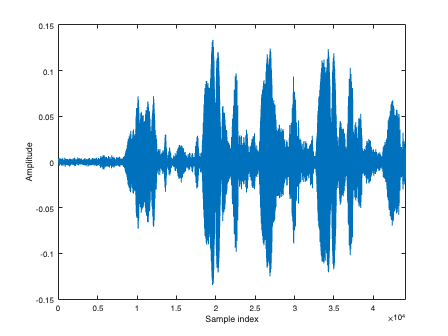

plot(audio)
xlim([0 numel(audio)])
xlabel('Sample index')
ylabel('Amplitude')

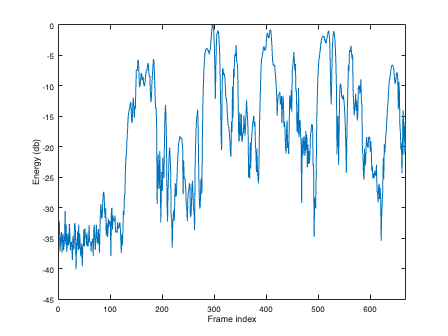

plot(energyDb)
xlim([0 numel(energyDb)])
xlabel('Frame index')
ylabel('Energy (db)')

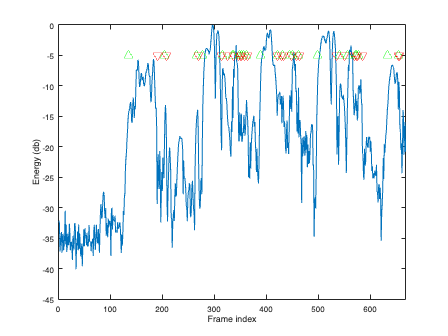

hold on
plot(find(onsets),-5,'g^','MarkerSize', 10)
plot(find(offsets),-5,'rv','MarkerSize', 10)
hold off

syllMidPoints = (syllableBoundaries(1:2:end)+syllableBoundaries(2:2:end))/2;
syllLabels = {'A', 'B', 'C', 'D', 'E', 'F', 'G'};

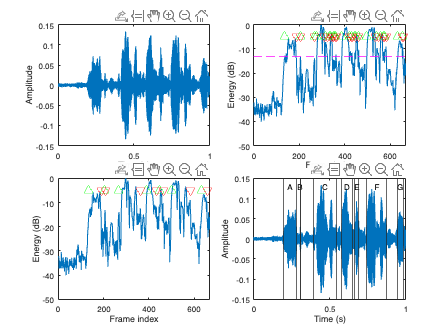

T = (0:numel(audio)-1)/fs;

t = tiledlayout(2,2);
t.TileSpacing = "compact";

ax1 = nexttile;
plot(ax1,T,audio)
% xlim([0 numel(T)])
xlabel('Time (s)')
ylabel('Amplitude')

ax2 = nexttile;
plot(ax2,energyDb)
hold(ax2,'on')
plot(find(onsets),-5,'g^','MarkerSize', 10)
plot(find(offsets),-5,'rv','MarkerSize', 10)
yline(threshDb,'m--')
% yline(noiseDb,'m-')
hold(ax2,'off')
xlim([0 numel(energyDb)])
xlabel('Frame index')
ylabel('Energy (dB)')

ax3 = nexttile;
plot(ax3,energyDb)
hold(ax3,'on')
plot(find(mergedOns),-5,'g^','MarkerSize', 10)
plot(find(mergedOff),-5,'rv','MarkerSize', 10)
hold(ax3,'off')
xlim([0 numel(energyDb)])
xlabel('Frame index')
ylabel('Energy (dB)')

ax4 = nexttile;
plot(ax4,T,audio)
hold(ax4,'on')
xline(syllableBoundaries/fs,'LineWidth',1)
text(syllMidPoints/fs,ones(1,7)*0.13,syllLabels,'HorizontalAlignment','center')
hold(ax4,'off')
% xlim([0 numel(T)])
xlabel('Time (s)')
ylabel('Amplitude')